# Práctica 2: Análisis de métodos de control de complejidad

## Abstract

Estudio estadístico que analiza el comportamiento de  los métodos de selección de modelos. Comparando k-CV, Bootstrap, y los métodos de penalización AIC y AICC. Utiliza la familia de funciones polinomiales  como funciones aproximadoras.

## Conjunto de datos

### Generación de datos teóricos (Población)

Para generar la función teórica se ha generado una muestra de 1000 ejemplos. Con ella calcularemos el ruido que usaremos para generar las muestras para realizar los experimentos.

clear all, close all

num_points = 1000;

%Definimos x e y.
x=4*(rand(1,num_points)-0.5);
yok=1.8 *tanh(3.2 * x + 0.8)- 2.5 * tanh(2.1 * x + 1.2)-0.2 * tanh(0.1 * x-0.5); 

%Definimos ruido y se lo añadimos a nuestra y.
RUIDO=0.2 * std(yok);
yruido=RUIDO * randn(size(yok));
y=yok+yruido;

plot(x,y,'.b'); hold on
plot(x,yok,'.k');  hold off
legend('Con ruido','Sin ruido');
title('Funcion Teórica')

## Métodos de remuestreo

### k-Cross-Validation

Uno de los métodos que usaremos será *k-cross-validation* , donde dividiremos la muestra en *k* partes iguales y donde usaremos una de ellas para validar el modelo y las *k* restantes para entrenarlo. El valor típico de *k* suele ser 10, aunque encontrar el *k* óptimo dependerá totalmente de nuestra muestra y representatividad de nuestros datos con respecto a la función subyacente.

n_sample = 50;
max_complex = 15;
n_experiments = 100;

for t=1:n_experiments
    
    index = randperm(1000, n_sample);
    xsample = x(index);
    ysample = y(index);
    
    if t == 1
        c = cvpartition(n_sample,'KFold',10);
        cnew = c;
    end

    for i=1:15
        fun = @(xTrain,yTrain,xTest,yTest)(mse(yTest - polyval(polyfit(xTrain, yTrain, i), xTest))); 
        cv_error(t, i) = sum(crossval(fun,xsample',ysample' ,'partition',cnew))/sum(cnew.TestSize);
    end
    

    cnew = repartition(c);
    
    
   [~ , best_model] = min(cv_error(t, :));
   best_local_model(t) = best_model;
end

plot(1:max_complex, mean(cv_error))
xlim([0, 15])
ylim([0, 0.5])

## Bootstrap

[bootstat, ~] = bootstrp(50, @mean, x');

## Dibujar varios boxplots

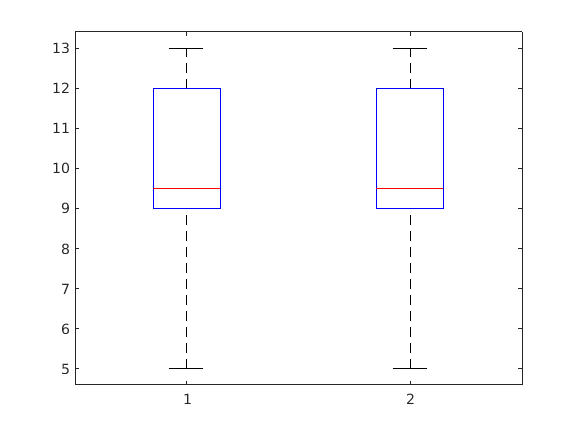

 boxplot([best_local_model', best_local_model'])